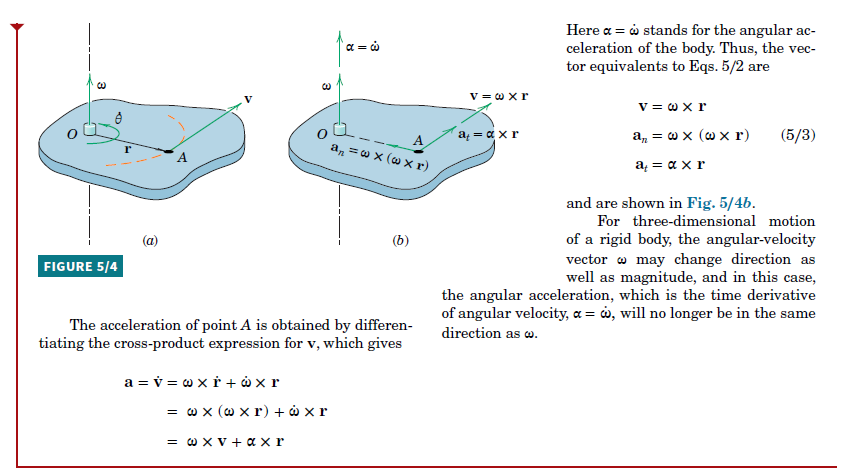

% Opgave 5.1
clc
clear
u = symunit;

w = 300/u.min; w2 = 900/u.min;
t = 6*u.s;

alpha = (w2 - w)/t;
vpa(simplify(unitConvert(alpha, "SI")),3)

theta = 1/2 * alpha * t^2 + w*t;

vpa(simplify(unitConvert(theta, "SI")),3)



% Opgave 5.3
clc
clear
u = symunit;

w = [0;0;4]/u.s;    alpha = [0;0;7]/u.s^2;

l1 = 0.5*u.m; l2 = 0.4*u.m;

l = sqrt(l1^2 + l2^2);

% Isoleret for vinklen plus givet vinkel

vinkel = asind(l2/l) + 20;
vpa(vinkel, 5)

x_l = cosd(vinkel) * l;
y_l = - sind(vinkel) * l; % Negativ grundet koordinatsystem
vpa(simplify([x_l; y_l]),2);

l_vec = [x_l; y_l; 0];

vpa(simplify(l_vec),3);

v = cross(w, l_vec);
vs = vpa(simplify(v),3)

a = -cross(w, v) + cross(alpha, l_vec);
as = vpa(simplify(unitConvert(a, "SI")),3)


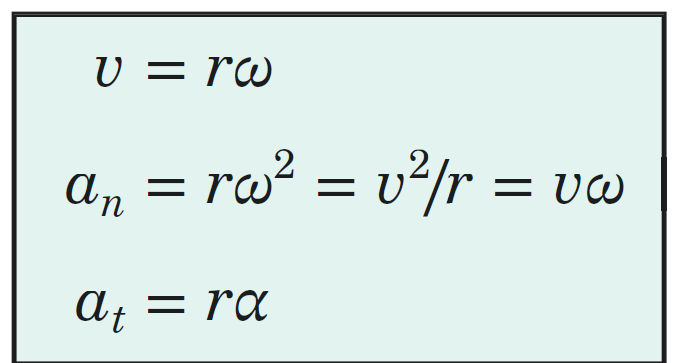

% 5.8
clc
clear
u = symunit;

r = 150*u.mm;
va = 0.6 * u.m/u.s; alpha_a = 4 * u.m/u.s^2;

w = va/r;
vpa(simplify(unitConvert(w, "SI")), 3)

alpha_n = r*w^2;
vpa(simplify(unitConvert(alpha_n, "SI")), 3)

alpha = sqrt(alpha_a^2 - (r*w^2)^2)/r;
vpa(simplify(unitConvert(alpha, "SI")), 3)


% 5.11
clc
clear
u = symunit;

m = 0.3*u.kg; alpha = 2 * 1/u.s^2; t = 3*u.s; r = 0.4*u.m;

g = 9.81*u.m/u.s^2;

% calculations
w = t * alpha;

an = r*w^2;
at = r*alpha;

a = sqrt(an^2 + at^2);
vpa(simplify(unitConvert(a, "SI")),3)

F = m*a;
vpa(simplify(unitConvert(F, u.N)),3)

% Angular displacement

theta = 1/2 * alpha * t^2;
vpa(simplify(unitConvert(theta, "SI")),3)


% 5.12
clc
clear
u = symunit;

a = 75 * u.m/u.s^2; v = 1.5*u.m/u.s;
r1 = 150*u.mm; r2 = 75*u.mm;

rs = [r1, r2];

% Acceleration af ydre og indre disc

w = v/r2;
vpa(simplify(unitConvert(w, "SI")), 3)


alpha = sqrt(a^2 - (r1*w^2)^2)/r1;
vpa(simplify(unitConvert(alpha, "SI")), 3)


% Total accel i pkt B
an = r2*w^2;
at = r2*alpha;
aB = sqrt(an^2 + at^2);
vpa(simplify(unitConvert(aB, "SI")), 3)



$$a\_n = \omega^{2}\,r$$

$$var = 12$$